## DKE Introduction to Bioinformatics 2022

# **Assignment 1**

*Elena Perego - i6238107*

### Sequence statistics and gene finding 

Like humans, Neanderthals had not only nuclear DNA, but also mitochondrial DNA in all their cells.  Like humans, the mitochondria of neanderthals contained 13 coding genes and 24 non-coding genes. The neanderthal mitochondrial genome has accession number 'NC_011137'.

- How does the number of genes stated above compare with the number of ORFs you find – explain your result. 

- Using what you have learnt above, explore the neanderthal mitochondrial genome and find at least one *interesting* feature. Explain what you have found and what makes it interesting.

Make a new livescript with your working and explanations for this part and submit this file to the assignment on canvas.

Make sure to explain what you want to do, then put the code that does it, then finalise each section with an explanation of what you see in the results (for instance how do you interpret the plot, or the numbers you obtained).  Repeat this pattern for each major step/result in your report.  

#### **Question 1:** *How does the number of genes stated above compare with the number of ORFs you find – explain your result. *

The ORFs are obtained using the inbuilt function **seqshoworfs**. However, among all ORFs, there are some that occur by chance in the sequence and are not real genes. Therefore, a minum length of the ORFs is calculated to reject those that are too short and likely not real gene. The length, $k$, that ensures with a 95.5% chance that a real gene is longer that would be expected by chance is calculates as $P\left(\mathrm{run}\;\mathrm{of}\;k\;\mathrm{non}\;\mathrm{stop}\;\mathrm{codons}\right)<0\ldotp 045$ 

First, the data is retrieved

data = getgenbank('NC_011137','SequenceOnly',true)

data = 'GATCACAGGTCTATCACCCTATTAACCACTCACGGGAGCTCTCCATGCATTTGGTATTTTCGTCTGGGGGGTGTGCACGCGATAGCATTGCGAGACGCTGGAGCCGGAGCACCCTATGTCGCAGTATCTGTCTTTGATTCCTGCCCCATTCCATTATTTATCGCACCTACGTTCAATATTACAGGCGAGCATACTTACTGAAGTGTGTTAATTAATTAATGCTTGTAGGACATAATAATAACGACTAAATGTCTGCACAGCTGCTTTCCACACAGACATCATAACAAAAAATTTCCACCAAACCCCCCCTCCCCCGCTTCTGGCCACAGCACTTAAACACATCTCTGCCAAACCCCAAAAACAAAGAACCCTAACACCAGCCTAACCAGATTTCAAATTTTATCTTTTGGCGGTATACACTTTTAACAGTCACCCCCTAACTAACACATTATTTTCCCCTCCCACTCCCATACTACTAATCTCATCAATACAACCCCCGCCCATCCTACCCAGCACACACCGCTGCTAACCCCATACCCCGAGCCAACCAAACCCCAAAGACACCCCCCACAGTTTATGTAGCTTACCTCCTCAAAGCAATACACTGAAAATGTTTAGACGGGCTCACATCACCCCATAAACAAATAGGTTTGGTCCTAGCCTTTCTATTAGCTCTTAGTAAGATTACACATGCAAGCATCCCCATTCCAGTGAGTTCACCCTCTAAATCACCACGATCAAAAGGGACAAGCATCAAGCACGCAACAATGCAGCTCAAAACGCTTAGCCTAGCCACACCCCCACGGGAAACAGCAGTGATAAGCCTTTAGCAATAAACGAAAGTTTAACTAAGCTATACTAACCCCAGGGTTGGTCAATTTCGTGCCAGCCACCGCGGTCACACGATTAACCCAAGTCAATAGAAGCCGGCGTAAAGAGTGTTTTAGATCACCCCCTCCCCAATAAAGCTAAAACTCACCTGAGTTGTAAAA

Then, the ORFs are found using the before mentioned inbuilt function. 

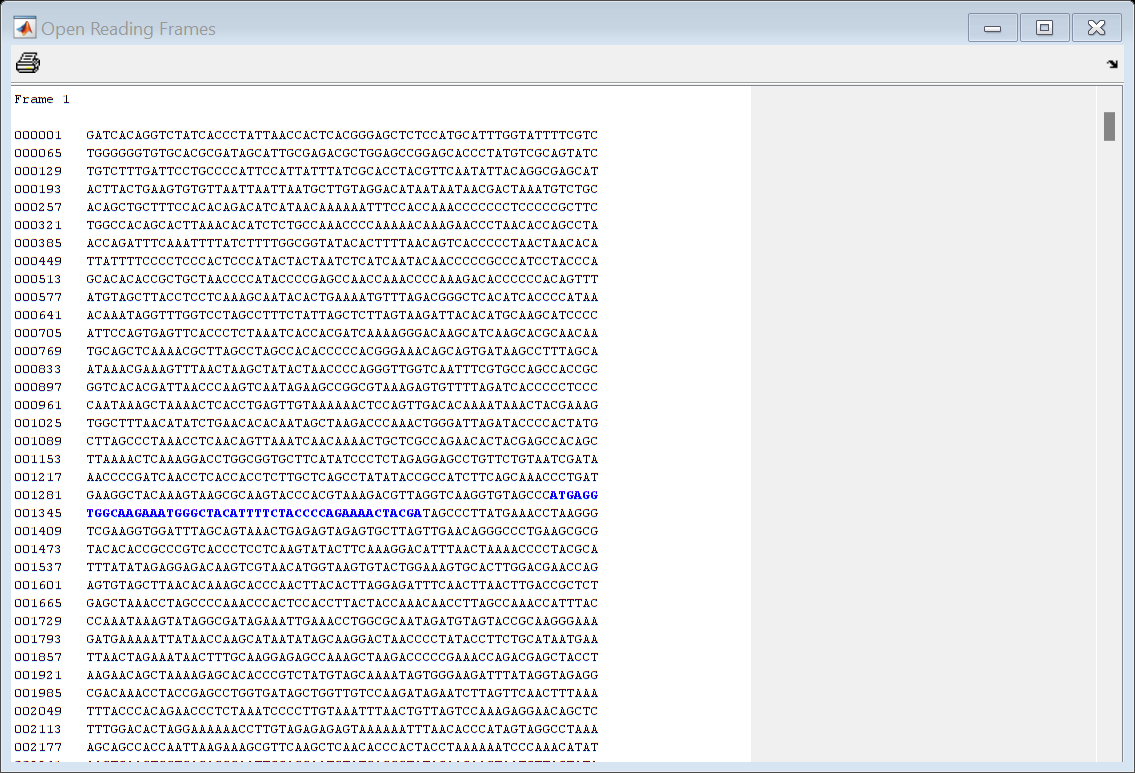

structure = 1×3 struct array with fields:
    Start
    Stop


structure = seqshoworfs(data)

Now, the probability of non stop codons is calculated based on the distribution of codons, which can be observed from the plot below. It is visible that codons, such as CCC, CTA, CCT, are more frequent than others. Therefore, it can be stated that the distribution is not normal.

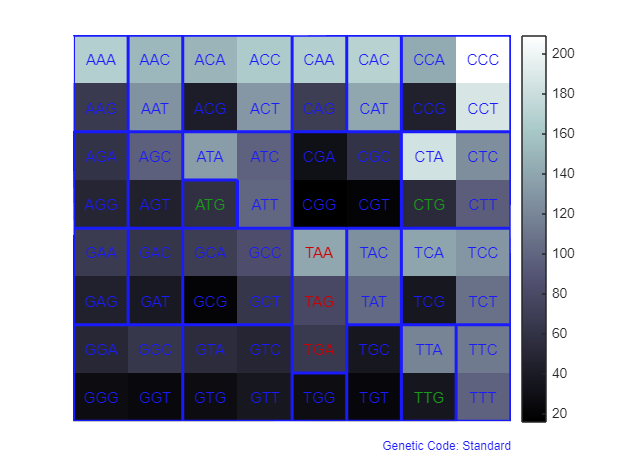

count = struct with fields:
    AAA: 168
    AAC: 151
    AAG: 66
    AAT: 128
    ACA: 149
    ACC: 164
    ACG: 42
    ACT: 131
    AGA: 61
    AGC: 96
    AGG: 49
    AGT: 45
    ATA: 135
    ATC: 98
    ATG: 58
    ATT: 100
    CAA: 168
    CAC: 170
    CAG: 69
    CAT: 141
    CCA: 142
    CCC: 209
    CCG: 45
    CCT: 187
    CGA: 31
    CGC: 61
    CGG: 16
    CGT: 20
    CTA: 184
    CTC: 125
    CTG: 53
    CTT: 95
    GAA: 67
    GAC: 63
    GAG: 45
    GAT: 38
    GCA: 69
    GCC: 84
    GCG: 20
    GCT: 63
    GGA: 50
    GGC: 64
    GGG: 27
    GGT: 25
    GTA: 55
    GTC: 49
    GTG: 27
    GTT: 37
    TAA: 141
    TAC: 126
    TAG: 79
    TAT: 102
    TCA: 139
    TCC: 130
    TCG: 37
    TCT: 107
    TGA: 66
    TGC: 37
    TGG: 28
    TGT: 23
    TTA: 119
    TTC: 113
    TTG: 36
    TTT: 98


figure
count = codoncount(data,'figure',true)

The probability of non stop codons for a non-uniform distribution is calculated as $1-P\left(\mathrm{TAA}\right)+P\left(\mathrm{TAG}\right)+P\left(\mathrm{TGA}\right)$, where $\mathrm{TAA},\;\mathrm{TAG},\;\mathrm{TGA}$ are the stop codonds. In this case, the probability results to $0\ldotp 9480$

frequency = 0;
number_frames = 3;
for i = 1:number_frames
    k = i;
    while k < length(data)-2
        codon = data(k:k+2);
        if isequal(codon,'TAA') || isequal(codon,'TAG') || isequal(codon,'TGA')
            frequency = frequency + 1;
        end
        k = k+3; 
    end
end
probability_stop = frequency/length(data)

probability_stop = 0.0520

probability_non_stop = 1-probability_stop

probability_non_stop = 0.9480

Solving for $k$ the equation $P\left(\mathrm{run}\;\mathrm{of}\;k\;\mathrm{non}\;\mathrm{stop}\;\mathrm{codons}\right)<0\ldotp 045$ is achieved as follows and results to 58.0984. This means that codons with length more than 58.0984 are 95.5 more likely to be true genes than by chance.


$$\begin{array}{l}
{1-P\left(\mathrm{TAA}\right)+P\left(\mathrm{TAG}\right)+P\left(\mathrm{TGA}\right)}^k =0\ldotp 045\\
k=\frac{\log \left(0\ldotp 045\right)}{\log \left(1-P\left(\mathrm{TAA}\right)+P\left(\mathrm{TAG}\right)+P\left(\mathrm{TGA}\right.\right)}
\end{array}$$


k = log(0.045)/log(probability_non_stop)

k = 58.0984

Now, the ORFs with length less than $k$ are rejected and the rest are counted. Indeed, the rest sums up to 13 real genes, which is the same as specified in the problem statement. Nevertheless, it si important to notice that the number of real genes changes based on the significance level, $\alpha$, which is now set to $0\ldotp 045$. This value should be lower than $0\ldotp 05$, which represents the maximum significance level to be commonly declared as a significant result. Decreasing the significance level increases the minimum length, $k$, and decreases the number of genes considered real.

count = 0;
for i = 1:3
    start = structure(i).Start;
    stop = structure(i).Stop;
    for j = 1:length(stop)
        if (stop(j)-start(j))/3 > k
            count = count+1;
        end
    end
end
count

count = 13

#### **Question 2: ***Using what you have learnt above, explore the neanderthal mitochondrial genome and find at least one interesting feature. Explain what you have found and what makes it interesting.*

Now, to explore the neanderthal mitochondrial genome and find interesting features, it is important to perform descriptive statistical analysis. Specifially, the distribution of bases and dimers is studied. Codons's distribution has been analyzed in the previous question. Moreover, it is easier to study dimers rather than codons and conclusions are quite similiar since there is only one base difference.

Here, the frequencies of the bases is shown.

NTStruct = basecount(data,'Ambiguous','individual')

NTStruct = struct with fields:
    A: 5107
    C: 5174
    G: 2180
    T: 4104
    R: 0
    Y: 0
    K: 0
    M: 0
    S: 0
    W: 0
    B: 0
    D: 0
    H: 0
    V: 0
    N: 0


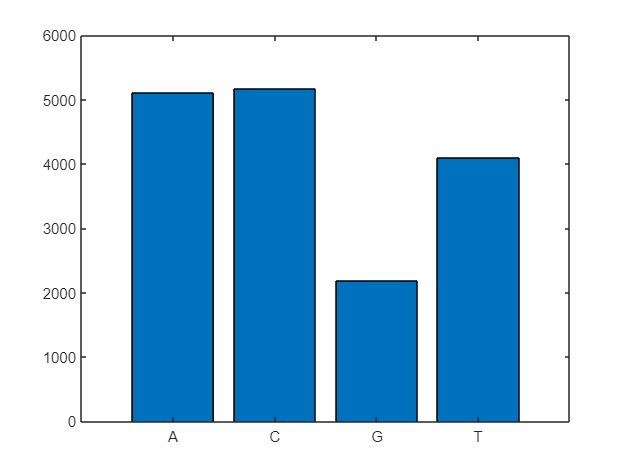

frequency = [NTStruct.A, NTStruct.C, NTStruct.G, NTStruct.T];
bar(categorical({'A','C','G','T'}),frequency)

From the Figure, there is a clear lack of Guanine compared to the others bases. Indeed, there are 2180 Guanine bases and 5107, 5174, 4104, of Adenine, Cytosine, and Thymine, respectively. Moreover, Adenine and Cytosine are the most frequent. This may look unexpected since Adenine pairs with Thymine and Cytosyine with Guanine, therefore, it would be expected to have similiar frequency within the same pair. However, this represents a single frequence of the neanderthal mitochondrial genome, hence, the frequencies of the pairs should not be compared in this histogram. Moreover, another interesting feature of the base's frequency is that there are no ambigous bases present, such as R, Y, K, M, S, W, B, D, H, V, and N.

Now, the percentage of each base in the sequence is analyzed in a Nucletotide Density Plot with a window frame of the length of the sequence divided by 20.

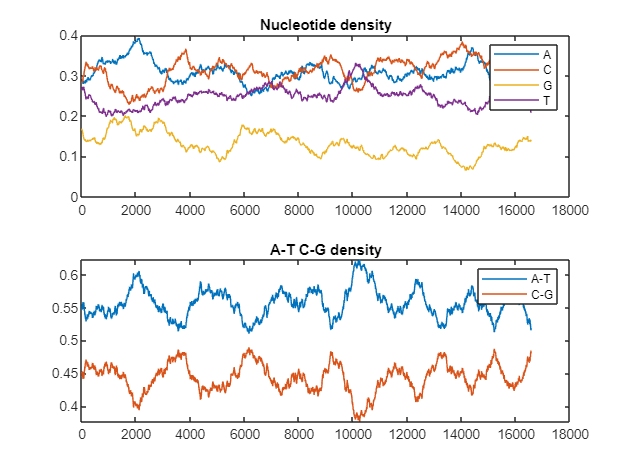

figure
ntdensity(data)

As previously said the second plot, which regards the pairs' frequencies, does not provide many results since it is based on only one sequence. However, it is visible that AT is more frequent with CG, which is congruent with the absence of Guanine. On the other hand, the first plot shows are all bases do not have the same probability of occuring through the whole sequence, since the curves often change drastically. Indeed, apart from Guanine, the most frequent base is different almost in very part of the sequence. From 800 till 3000, Adenine is more frequent, whereas from 3000 till 5000 Cytosine is. Therefore, to study this genome, the Markov sequence model would be a better fit than the Monomial Model, whose assumption is that the bases are identically and independent distributed.

Moving on with the dimers, the 3D histogram below confirms the low frequence of Guanine and its corresponding dimers, and it shows that C is the most frequent first base.

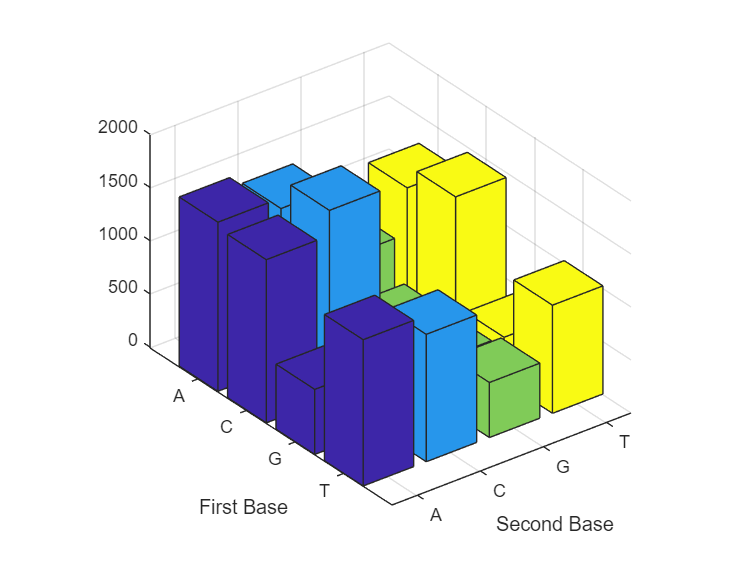

dimers = struct with fields:
    AA: 1589
    AC: 1490
    AG: 799
    AT: 1229
    CA: 1533
    CC: 1769
    CG: 431
    CT: 1441
    GA: 611
    GC: 718
    GG: 432
    GT: 418
    TA: 1374
    TC: 1197
    TG: 517
    TT: 1016


figure
dimers = dimercount(data,'chart', 'bar')

Now, to take a better look at unexpected behavior in the frequency of dimers, the odd ratios table is constructed based on the relative frequency of the different bases in the studied genome.

The relative frequencies are computed by dividng the number of occurences with the total number of nucleotides.

frequency_table = struct2table(dimers);
total = sum(frequency_table{1:1,1:end}, 'All');
for i = 1:width(frequency_table)
    frequency_table{1,i} = frequency_table{1,i}/total;
end

Then, to change the structure of the table, it has been typed on excel and imported as it looks in the following figure. 

frequency_table = readtable("frequency_table.xlsx",'ReadRowNames',true)

frequency_table = 5×5 table
               A         C         G         T       Total 
             ______    ______    ______    ______    ______

    A        0.0959      0.09    0.0482    0.0742    0.3083
    C        0.0926    0.1068     0.026     0.087    0.3124
    G        0.0369    0.0433    0.0261    0.0252    0.1315
    T         0.083    0.0723    0.0312    0.0613    0.2478
    Total    0.3084    0.3124    0.1315    0.2477         1


The odd ratio compares the observed and the expected frequencies and it is calculated as follows.


$$\mathrm{odd}\;\mathrm{ratio}\approx \frac{N\left(\mathrm{xy}\right)}{N\left(x\right)N\left(y\right)}$$


where $N\left(\mathrm{xy}\right)$ is the observed frequency, which represented the frequency observed from the data, and $N\left(x\right)N\left(y\right)$ is the expected frequency, which is the probability of one base occuring together (multiplied) with the probability of the other one. If the odd ratio is close to 1, it means that the dimer is present and expected. On the other hand, the further the odd ratio is from 1, the dimer is more or less present than expected.

odd_ratios = frequency_table;
for i = 1:width(odd_ratios)
    for j = 1:height(odd_ratios)
        odd_ratios{i,j} = frequency_table{i,j}/(frequency_table{i,"Total"}*frequency_table{"Total",j});
    end
end
odd_ratios

odd_ratios = 5×5 table
                A          C          G          T       Total
             _______    _______    _______    _______    _____

    A         1.0086    0.93445     1.1889    0.97164      1  
    C        0.96114     1.0943     0.6329     1.1243      1  
    G        0.90988      1.054     1.5093    0.77366      1  
    T         1.0861    0.93396    0.95748     0.9987      1  
    Total          1          1          1          1      1  


From the odd ratios table, for example, it is visible that CG occurs 40% less than expected, but GC is present approximately as expected. Then, it is interesting to see that the most unexpected dimers are GG, CG, GT, and AG, since they occur 50% more, 40% less, 30% less, and 20% more than expected, respectively. Since all of these unexpected imers include G, this behavior may be explained by the important difference in occurence of Guanine compared to the other bases.

Therefore, to summarize, in the neanderthal mitochondrial genome, it is interesting to notice:

- the lack of Guanine

- the non presecens of ambiguous bases

- the frequent and drastic change of the density of the nucleotides

- Cytosyine is the most frequent first base

- the frequencies of the dimers, GG, CG, GT, and AG in the sequence are the most unexpected 